# splWindows

A script to calculate a lobing pattern of tonal and broadband sound pressure level measurements at an array of hydrophones from a passing ship using its AIS track. By grouping all of the consecutive measurements along the ships track by same look angle (azimuth), the lobing characteristics of the ship's noise signature can be estimated. 

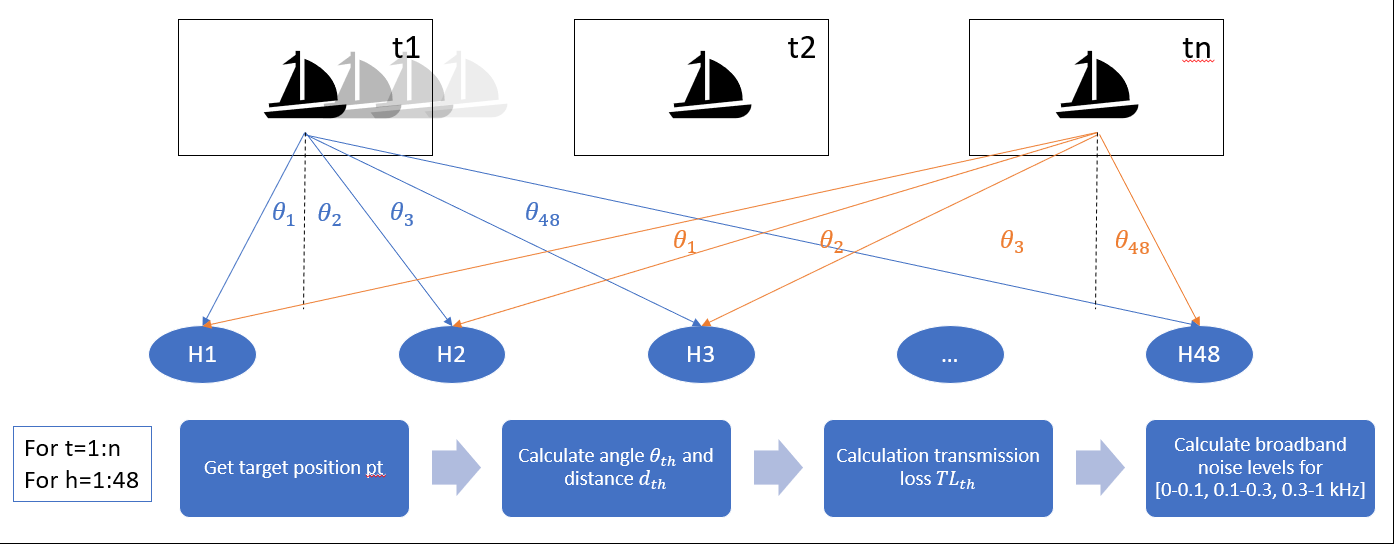

## Initialize & set parameters

clearvars

load arrays_lat-long
array1=table2array(array1(:,1:2));
array2=table2array(array2(:,1:2));

## Load AIS file

load byShip.mat
AIS = Heb_Sky;   %select ship of interest
AIS = sortrows(AIS,'datetime','ascend');
AIS(1:792,:) = [];  % need to find a way to filter out by +/- CPA time  --> 26-Aug-2015 17:30:00 
AIS(330:end,:) = [];

## Calculate ranges along ship track

[R1,R2] = calcDist(AIS.lat, AIS.long, array1, array2);

### Plot bearing histogram of ranges

rangeRoser(R2(:,1,2), R2(:,1,1), 'legendtype', 1, 'anglenorth', 0, 'angleeast', 90, 'lablegend', 'Distance (km)')
set(gca,'FontSize',14)

## Calculate TL for each window location

TL1 = 10*log(R1(:,24,1)*1000);
TL2 = 10*log(R2(:,24,1)*1000);   %for one centre hph location only

## Load acoustic data

multi = 'singleCh.wav';           % Select the 48-ch (allCh) or 1-ch (singleCh) file
NWFile = fullfile('C:\Users\510PAS\PhD\Data\NW\HebSky\proc',multi);
[x,fs] = audioread(NWFile);
t = cumsum(ones(size(x(:,1)))/fs); % time vector

### Calculate Received SPL

ans =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [600 180 720 720]
       Units: 'pixels'

  Show all properties


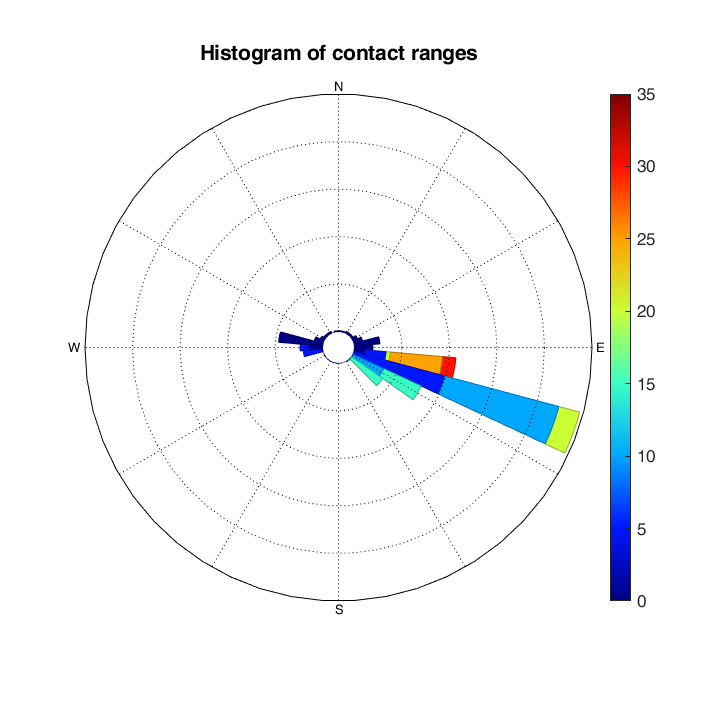

SPL = spl(x,1e-6,60,fs);     % calculate SPL using spl sub-routine with 1-sec windows re 1uPa

### Plot signal and SPL

figure
subplot(2,1,1)
plot(t,x)
axis tight
ylabel('pressure (Pa)')

subplot(2,1,2)
plot(t,SPL)
axis tight
ylabel('spl (dB)')
xlabel('time (s)')